clc; clear all
dbclear if warning

%% ---------------- Parameters (from tables) ----------------
% (Keep both original units and SI where convenient)
Cs10 = 1.08e-10;     % [F]  RF sheath S1 equivalent capacitance constant term
Cs20 = 3.24e-10;     % [F]  Grounded sheath S2 equivalent capacitance constant term

Ii1  = 0.0021;       % [A]  Ion current in sheath S1
Ii2  = 0.0064;       % [A]  Ion current in sheath S2

Ie10 = 0.91;         % [A]  Electron current constant term in sheath S1
Ie20 = 2.74;         % [A]  Electron current constant term in sheath S2

Rpl  = 15.51;        % [Ohm] Plasma bulk equivalent resistance
Lpl  = 2.59e-7;      % [H]   Plasma bulk equivalent inductance

% ---- Geometry / circuit / operating conditions ----
AE_cm2 = 100;        % [cm^2] Powered electrode area
AG_cm2 = 300;        % [cm^2] Ground electrode area
AE     = AE_cm2 * 1e-4;   % [m^2]
AG     = AG_cm2 * 1e-4;   % [m^2]

lbulk_cm = 5.7;      % [cm]   Plasma bulk length
lbulk    = lbulk_cm * 1e-2;  % [m]

Rrf   = 50;          % [Ohm] Equivalent source internal resistance
Rm    = 0.5;         % [Ohm] Equivalent series resistance
Rstray= 0.5;         % [Ohm] Stray parallel branch resistance
Cstray= 200e-12;     % [F]   Stray parallel branch capacitance (200 pF)

Lm2   = 1500e-9;     % [H]   Series matching inductance (1500 nH)
% Cm1   = 1550e-12;    % [F]   Shunt matching capacitance (1550 pF)
% Cm2   = 175e-12;     % [F]   Series matching capacitance (175 pF)

p_mTorr = 5;         % [mTorr] Gas pressure ~= 0.667Pa
p       = 0.667;
Tg      = 300;       % [K]     Gas temperature
Te      = 4.75;      % (as given) Electron temperature
ne      = 1.25e15;   % [m^-3]  Electron density (4.5 W)

Vrf   = 100;         % [V]   RF source voltage amplitude (25 W)
frf   = 13.56e6;     % [Hz]  RF source frequency
% wrf   = 2*pi*frf;    % [rad/s]

%% ---------------- Parameters (from tables) ----------------
% (Keep both original units and SI where convenient)

% ---- Sheath / plasma lumped parameters ----
Cm1   = 1550e-12;    % [F]   Shunt matching capacitance (1550 pF)
Cm2   = 175e-12;     % [F]   Series matching capacitance (175 pF)
wrf   = 2*pi*frf;    % [rad/s]

par = [Cm1; Cm2; wrf];


pnames = {'Cm1', 'Cm2', 'wrf'};
p0     = par;
% initial solution guess
opts = odeset('RelTol',1e-8,'AbsTol',1e-10);
[t0,x0]  = ode15s(@(t,x) ccp_ode_KVL(t,x,par), [0, 15000/wrf], zeros(7,1), opts);
t_test = t0(end);
x_test = x0(end,:)';
% [t0,x0] = ode15s(@(t,x) ccp_ode_KVL(t,x,par), [0, 2*pi/wrf], x0(end,:), opts);

% trunc1 = round(length(t0) * 0.985);
% t0 = t0(trunc1:end);
% x0 = x0(trunc1:end, :);



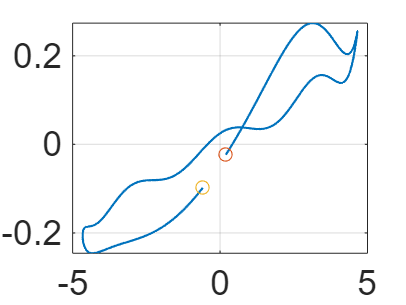

trunc1 = round(length(t0) * 0.99959);
figure; hold on
plot(x0(trunc1:end,4), x0(trunc1:end,5), 'LineWidth', 1);
scatter(x0(trunc1,4),  x0(trunc1,5))
scatter(x0(end,4),     x0(end,5))
box on
grid on
set(gca, fontsize=16)


% t0 = t0(trunc1:end);
% x0 = x0(trunc1:end,:);

## 导数验证

% dx_base = ccp_ode_KVL(t_test, x_test, par); % 原始dx值

% delta_t      = eps;
% dccp_dt      = ccp_ode_KVL_dt(t_test, x_test, par)
% dccp_dt_diff = (ccp_ode_KVL(t_test+delta_t,x_test,par) - dx_base) / delta_t

% % ============== 验证dx_dx ======================
% % 差分扰动步长h（百万分之一的扰动）
% h = 1e-6 + 1; 
% 
% % ===================== 2. 计算解析雅可比矩阵（你的函数） =====================
% J_analytic = ccp_ode_KVL_dx(t_test, x_test, par)
% 
% % ===================== 3. 中心差分法计算数值雅可比矩阵 =====================
% n = length(x_test); % 状态维度（7）
% J_numeric = zeros(n, n); % 初始化数值雅可比
% 
% 
% % 对每个状态分量x_j施加扰动，计算差分
% for j = 1:n
%     % 构造扰动向量（仅第j个分量±h）
%     x_plus = x_test;  x_plus(j) = x_plus(j) * h;
% 
%     % 计算扰动后的dx
%     dx_plus = ccp_ode_KVL(t_test, x_plus, par);
% 
%     % 中心差分计算第j列雅可比（精度更高）
%     J_numeric(:, j) = (dx_plus - dx_base) / (x_plus(j) - x_test(j));
% end
% J_numeric
% abs_error = abs(J_analytic - J_numeric); % 逐元素绝对误差
% rel_error = abs_error ./ (abs(J_analytic) + eps) % 相对误差（加eps避免除零）

% % ============== 验证dx_dCm1, dx_dCm2 ======================
% h = 1e-6 + 1; 
% 
% dp_analytic = ccp_ode_KVL_dp(t_test, x_test, par); % dx/dCm1解析解
% % ---- 3.1 计算dx/dCm1的数值近似 ----
% par_plus_p = par;   par_plus_p(1) = Cm1 * h; 
% dx_plus_p1 = ccp_ode_KVL(t_test, x_test, par_plus_p); 
% 
% par_plus_p = par;   par_plus_p(2) = Cm2 * h; 
% dx_plus_p2 = ccp_ode_KVL(t_test, x_test, par_plus_p); 
% 
% par_plus_p = par;   par_plus_p(3) = wrf * h; 
% dx_plus_p3 = ccp_ode_KVL(t_test, x_test, par_plus_p); 
% 
% dp_numeric = [(dx_plus_p1 - dx_base) / (Cm1 * h - Cm1),...
%               (dx_plus_p2 - dx_base) / (Cm2 * h - Cm2),...
%               (dx_plus_p3 - dx_base) / (wrf * h - wrf)];
% 
% abs_error_p = abs(dp_analytic - dp_numeric); % 逐元素绝对误差
% rel_error_p = abs_error_p ./ (abs(dp_analytic) + eps) % 相对误差（加eps避免除零）
% % 
% 


prob = coco_prob();
prob = coco_set(prob, 'ode', 'autonomous', false);
prob = coco_set(prob, 'coll', 'NTST', 30);
coll_func = {@ccp_ode_KVL, @ccp_ode_KVL_dx, @ccp_ode_KVL_dp, @ccp_ode_KVL_dt};
coll_args = [coll_func, {t0, x0, pnames, p0}];
prob = ode_isol2po(prob, '', coll_args{:});

[data, uidx] = coco_get_func_data(prob, 'po.orb.coll', 'data', 'uidx');
maps = data.coll_seg.maps;
% monitor amplitude
ampdata.dof  = 4;
ampdata.zdim = 7;
prob = coco_add_func(prob, 'amp1', @amplitude_po, ampdata, ...
        'regular', {'|I2|'}, 'uidx',...
         uidx(maps.xbp_idx), 'remesh', @amplitude_remesh_po);
% prob = coco_add_func(prob, 'amp1', @amplitude_po, ampdata, ...
%         'regular', {'|Q1|','|Q2|','|Q3|','|I2|','|I3|','|Qs1|','|Qs2|'}, 'uidx',...
%          uidx(maps.xbp_idx), 'remesh', @amplitude_remesh_po);

prob = coco_set(prob, 'cont', 'NAdapt', 1);
% coco(prob, 'run', [], 1, 'Cm1', [Cm1*0.1, Cm1*10]);
coco(prob, 'run', [], 1, 'wrf', [wrf*0.9, wrf*1.1]);

sol = po_read_solution('run',12);
[~,x1] = ode15s(@(t,x) ccp_ode_KVL(t,x,par), [0, 2*pi/wrf], sol.xbp(1,:)', opts);

figure; hold on
plot(sol.xbp(:,4), sol.xbp(:,5), 'r-')
plot(x1(:,4), x1(:,5), 'b--', 'LineWidth', 1);

% bd1 = coco_bd_read('isolep');
% bd_data_bd = bd_data{4,2}; 
% wrfsss = bd_data_bd(2:end,10);
% I2ssss = bd_data_bd(2:end,19);
% figure;
% plot(cell2mat(wrfsss), cell2mat(I2ssss))

% figure; 
% coco_plot_bd('run','wrf','|I2|')

% ans0 = ccp_ode_KVL_dt(linspace(0,0.01,10), x_test, par);
% ans1 = ccp_ode_KVL(0.01, x_test, repmat(par,1,3));
% ans2 = ccp_ode_KVL_dx(0.01, repmat(x_test,1,5), par);
% ans3 = ccp_ode_KVL_dCm1(0.01, x_test, repmat(par,1,3));
% ans4 = ccp_ode_KVL_dCm2(0.01, x_test, repmat(par,1,6));





